# Zadatak 2

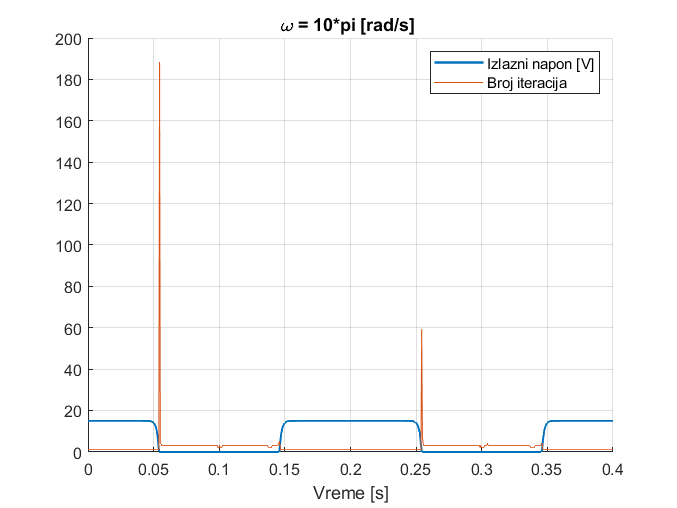

clc;clear ;close all

Vcc=15;
Rc=10e3;
w=10*pi;
alfaf=100/101;
alfar=1/2;
Is=0.01e-12;
Vt=25e-3;
N=360; % Broj tacaka 
Nit=5e2; %Maks broj iteracija

epsa=1e-12;
epsr=1e-3;

%Postavljanje jednacina kola
syms V1 V2 V3 V1a V1b I1 I3 Ir If Ieqf Ieqr gr gf vin
e1=I1+(1-alfar)*Ir+(1-alfaf)*If==0;
e2=gr*(V1a-V2)-Ir==-Ieqr;
e3=gf*V1b-If==-Ieqf;
e4=gr*(-V1a+V2)+1/Rc*(+V2-V3)+alfaf*If==Ieqr;
e5=1/Rc*(V3-V2)+I3==0;
e6=V1==vin;
e7=V3==Vcc;
e8=V1-V1a==0;
e9=V1-V1b==0;
e=[e1 e2 e3 e4 e5 e6 e7 e8 e9];
var=[V1 V2 V3 V1a V1b I1 I3  Ir If];
s=solve(e,var);
vout=matlabFunction(s.V2);
ir=matlabFunction(s.Ir);


t=linspace(0,2*2*pi/w,2*N);
vin=0.5*(1-cos(w*t));
Ieqf=Is/alfaf*(exp(vin/Vt)-1);
gf=Is/alfaf*exp(vin/Vt)/Vt;
y=zeros(3,2*N);
vout0=0;

%Resavanje nelinarnog kola
for k=1:2*N
    p=1;
    while(p<Nit)
        
        gr = Is/alfar*exp((vin(k)-vout0)/Vt)/Vt;
        Ieqr=Is/alfar*(exp((vin(k)-vout0)/Vt)-1)-gr*(vin(k)-vout0);
        Ir_lin=ir(Ieqf(k),Ieqr,gf(k),gr,vin(k));
        vout0=vout(Ieqf(k),Ieqr,gf(k),gr,vin(k));
        
        Ir1 = Is/alfar*(exp((vin(k)-vout0)/Vt)-1);
        %kada je razlika manja od 1nA prekini
        if abs(Ir_lin-Ir1) < 1e-9
           break;
        end
        
        p=p+1;
        
    end
   
    if p==Nit
        error('Convergence error');
    end
     
    y(1,k)=vout0;
    y(2,k)=p;
end
hold all;
plot(t,y(1,:),'LineWidth',1.5);
plot(t,y(2,:));
xlabel('Vreme [s]')

title('\omega = 10*pi [rad/s] ')
grid on
legend('Izlazni napon [V]','Broj iteracija');